# Homework 3 

## Problem 1: Energy Conservation

The solution to the simple harmonic motion of the pendulum (the small angle approximation with $\omega_0 =9$, $\theta_0 =0\ldotp 25$, and $\dot\theta_0 = 0$) is given by the MATLAB function *pendulum2.m. *Below this program with produce a graph of the solutions and the phase diagram.

theta0=0.25;
omega0=3;
thetadot0=0;
[t,w]=pendulum2(1,1,omega0,theta0,thetadot0);

The phase diagram in this instance will always be an ellipse whose semi-major and semi-minor axis are determined by the intial conditions of the problem. Considering the motion of the pendulum, the phase diagram should always be drawn in a CCW fashion. When the angle $\theta$ is initial positive, the angular velocity $\dot\theta_0$ is initial negative. the angular velocity only comes positive after the pendulum has swung to the other extreme.

From the solution from *pendulum2.m* we can calculate the kinetic, potential, and total energy, as well as the change in energy through one cycle by noting that 


$$E = \frac{1}{2}mL^2\dot{\theta^2}+mgL(1-\cos{\theta}) = \frac{g^2}{2\omega_0^4}\dot{\theta^2} + \frac{g^2}{2\omega_0^2}(\theta^2)
$$


taking *m=1*.

g=9.81;
[Tsmall,ind] = cyclefinder(t,w);
[KEn,PEn,DeltaE] = energyfinder(t,w,1);
plot(t,DeltaE)
xlabel('time')
ylabel('\Delta E/E_0')

So, the energy is conserved approximately 1 part in 10,000 every cycle. You can hardly notice it when graphing the energies

plot(t,KEn,'r--',t,PEn,'b--',t,KEn+PEn,'k')
xlabel('time')
ylabel('Energy')
legend('KE','PE',['E_{tot}'])

## **Problem 2: Large Oscillations**

For large oscillations, the equation of motion becomes $\ddot{\theta} = -\frac{g}{L}\sin{\theta} = \omega_0^2 \sin{\theta}$, which is coded in the program pendulum2.m already,

g=9.81;
theta0=1;
omega0=3;
thetadot0=0;
[t,w] = pendulum2(2,1,omega0,theta0,thetadot0);

The energy is then calculated as 


$$E = \frac{g^2}{2\omega_0^4}\dot{\theta}^2+\frac{g^2}{\omega_0^2}(1-\cos{\theta})$$


Again, assuming *m=1*,

[KEn,PEn,DeltaE] = energyfinder(t,w);
plot(t,DeltaE)
plot(t,KEn,'r--',t,PEn,'b--',t,En,'k-')

The total energy does flucuate about 1 in 1000 parts per oscillation. The change in energy is noticeable in the enregy plot as well. 

Looking at different starting conditions,

theta = [0.1,0.2,0.4,0.8,1];
color = ['k','b','r','c','g'];

for k = 1:length(theta)
    [t,w] = pendulum2(2,0,omega0,theta(k),thetadot0);
    plot(t,w(:,1),color(k))
    hold on
    lab(k) = sprintf('\\theta_0 = %f',theta(k));
    T(k) = cyclefinder(t,w);
end
xlabel('time')
ylabel('angle')
legend(lab)
hold off

You can see that as the initial angle gets larger, then the period of oscillation gets longer. Whereas the small angle approximation period did not depend on the initial condition

plot(theta,T)
xlabel('\theta_0')
ylabel('Period')

## **Problem 3: Damped Oscillations**

When incorporating a damping term,

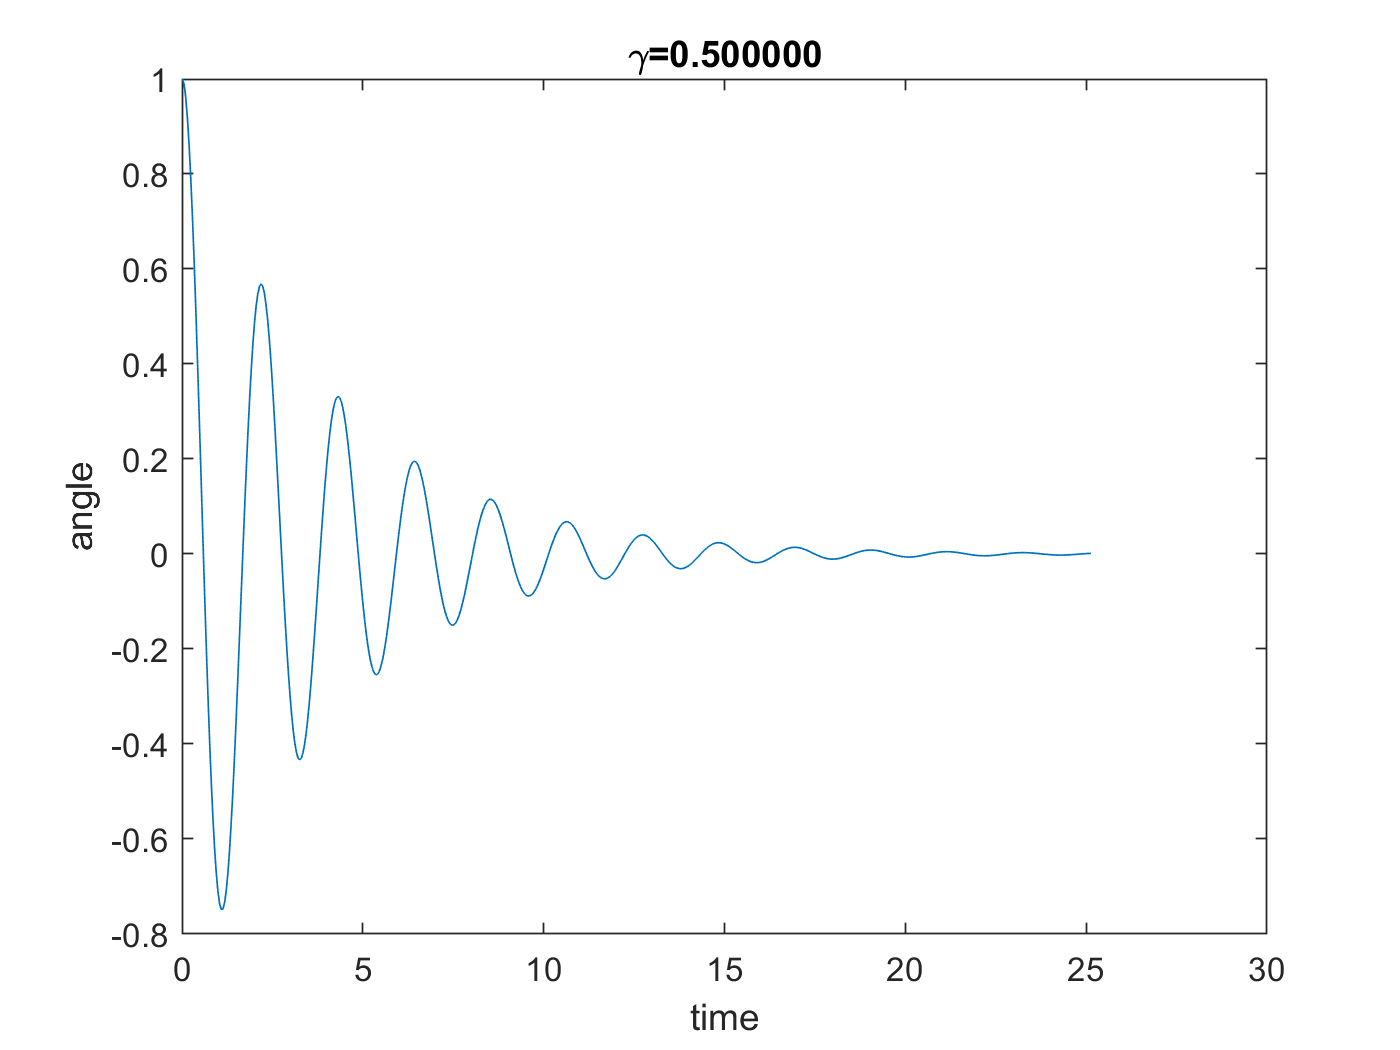

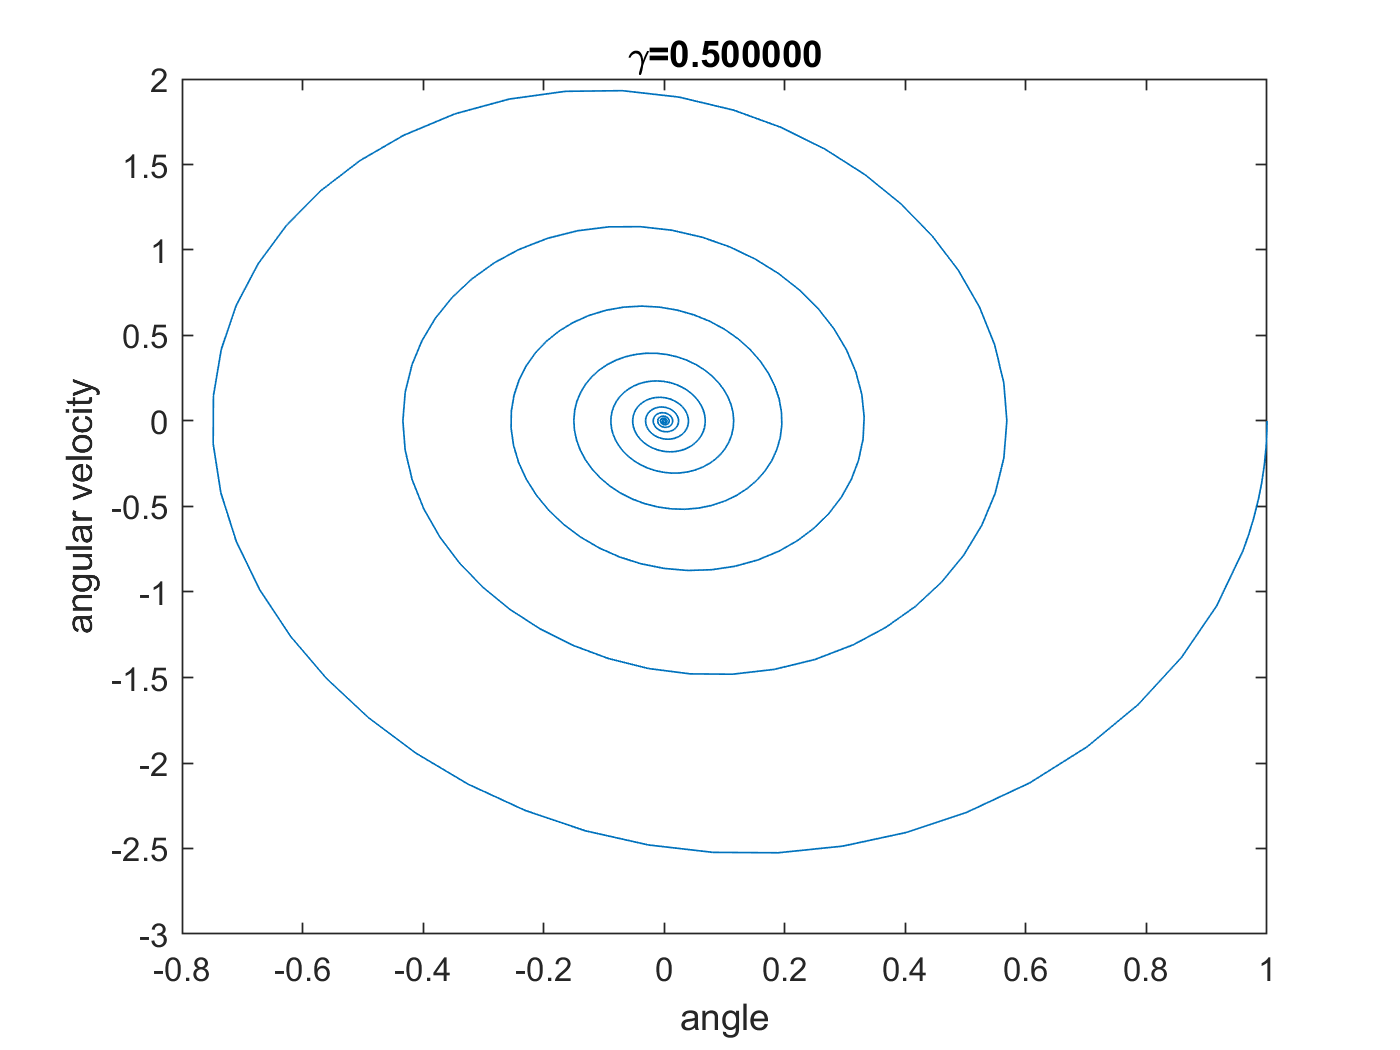

clear
g=9.81;
theta0=1;
omega0=3;
thetadot0=0;
gamma = 0.5;
[t,w] = pendulum2(3,1,omega0,theta0,thetadot0,gamma);

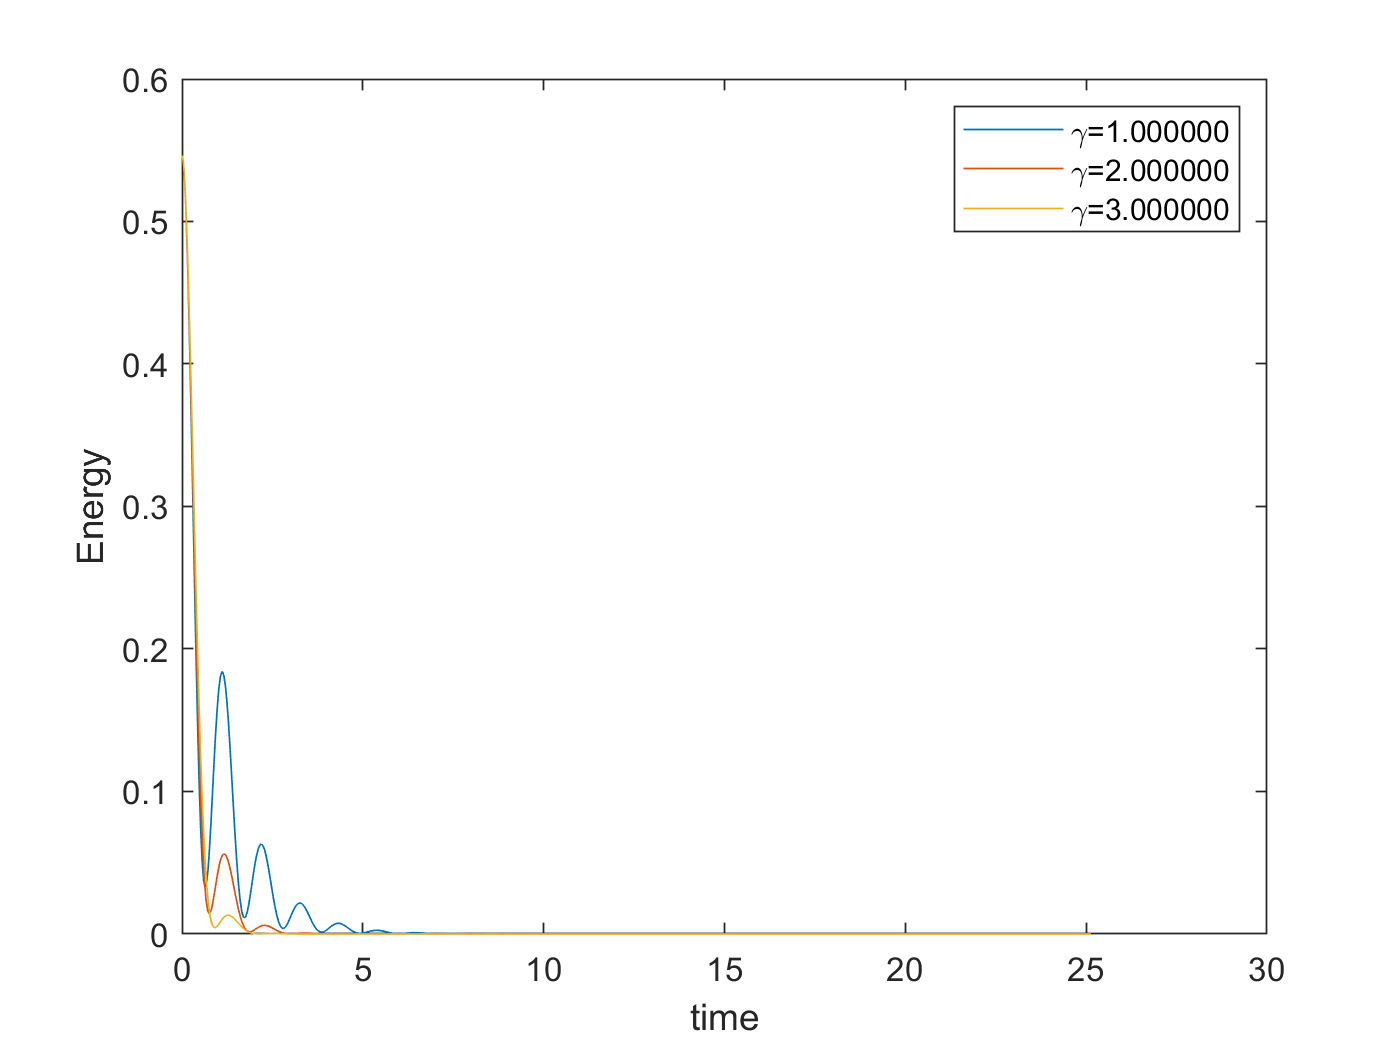

gamma = [1,2,3];

for k = 1:length(gamma)
    [t,w] = pendulum2(3,0,omega0,theta0,thetadot0,gamma(k));
    T(k) = cyclefinder(t,w);
    [KEn,PEn,DeltaE] = energyfinder(t,w);
    damplab(k) = sprintf("\\gamma=%f",gamma(k));
    plot(t,KEn+PEn)
    hold on
end
legend(damplab)
xlabel('time')
ylabel('Energy')
hold off

The total energy oscillates and does not decrease uniformly in this simulation.

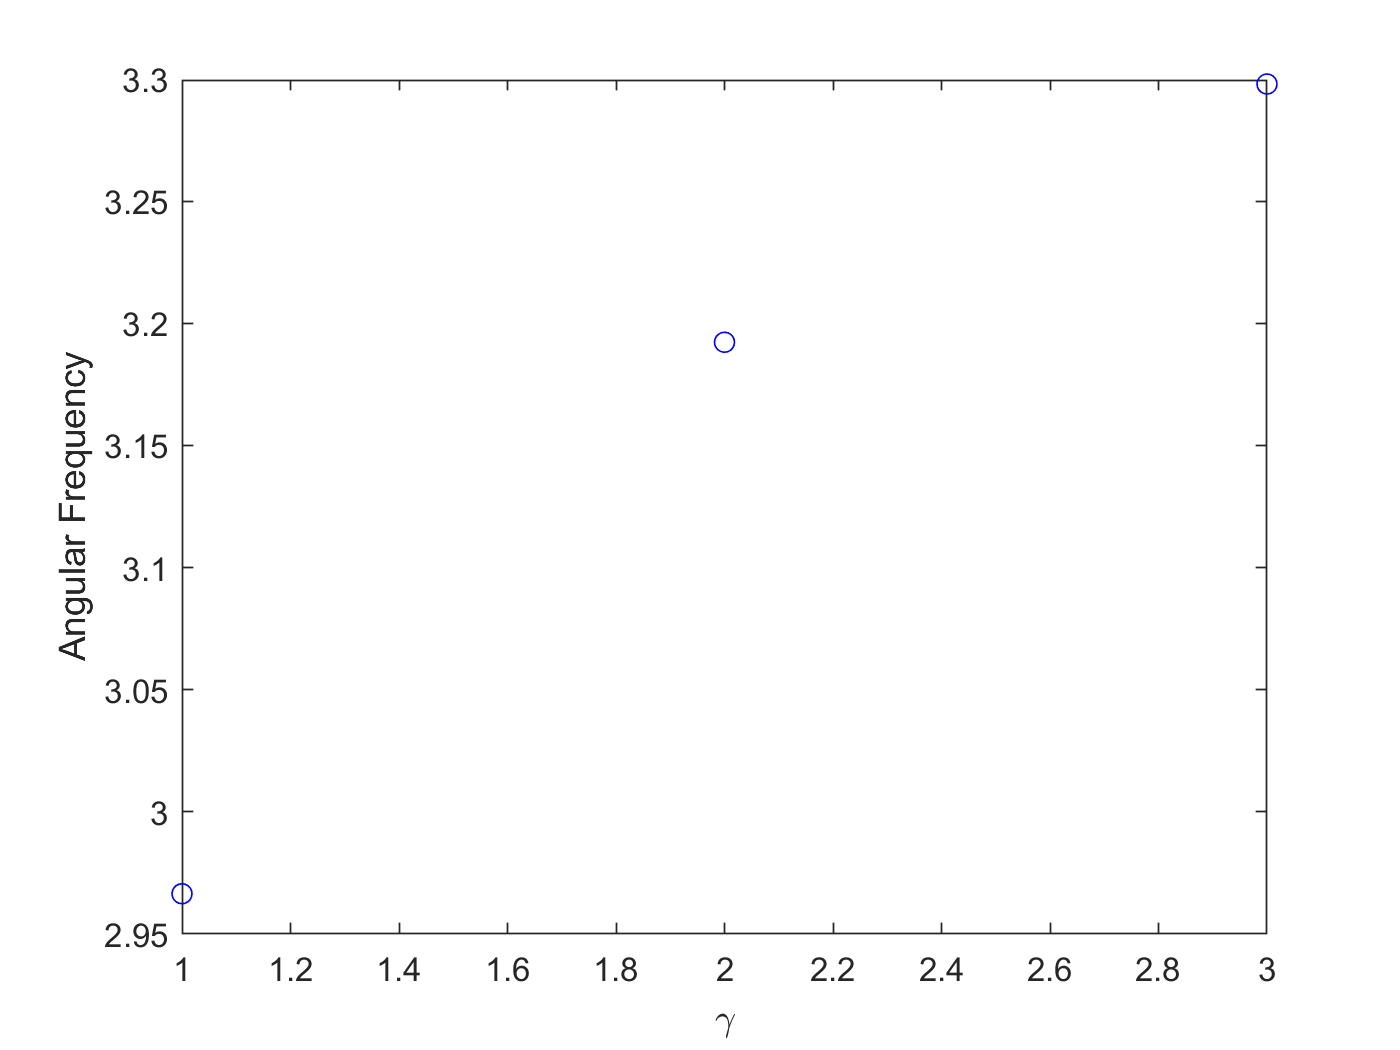

plot(gamma,2*pi./T,'bo')
ylabel('Angular Frequency')
xlabel('\gamma')

The period increases with increasing damping, so the angular frequency decreases with increasing damping (as expected).

Oscillatory motion does not occur for all values of $\gamma$. The motion stops being oscillatory around $\gamma\approx 2\omega_0$ (in our case $\gamma\approx 6$)

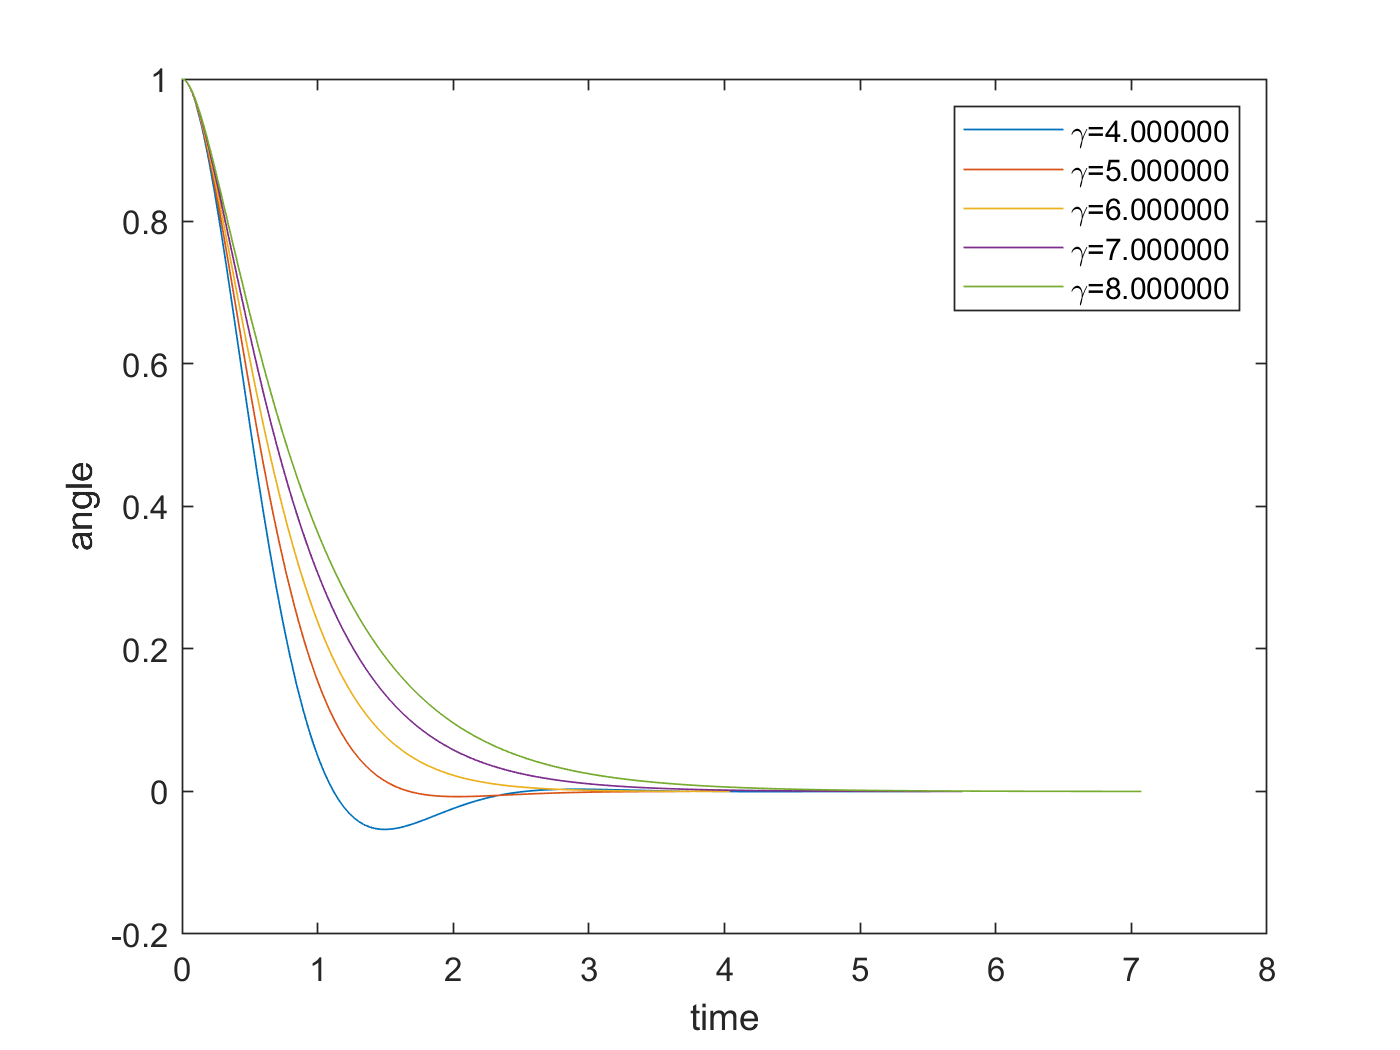

gamma = 4:8;
for k = 1:length(gamma)
     if k==1
        sol = struct('run1',0);
        fn = 'run1';
    else
        fn = sprintf('run%i',k);
    end
    [t,w] = pendulum2(4,0,omega0,theta0,thetadot0,gamma(k));
    sol = setfield(sol,fn,[t w]);
    T(k) = t(end);
end
solnames = fieldnames(sol);
for k = 1:length(solnames)
    W = getfield(sol,solnames{k});
    plot(W(:,1),W(:,2))
    hold on
    leglab(k) = sprintf("\\gamma=%f",gamma(k));
end
legend(leglab)
xlabel('time')
ylabel('angle')
hold off

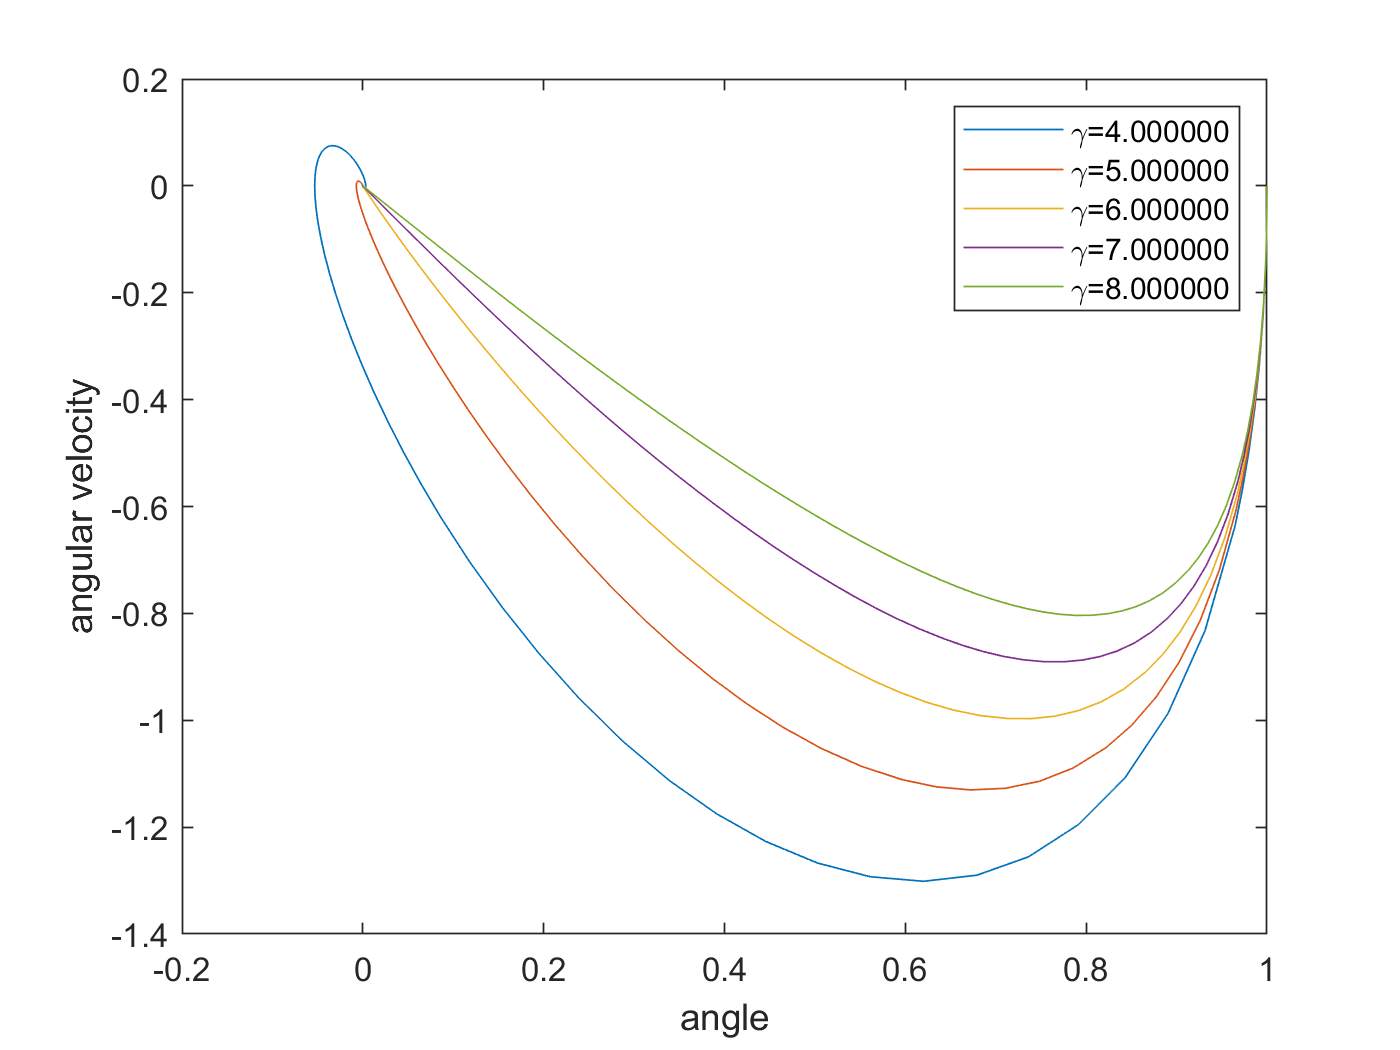

for k = 1:length(solnames)
    W = getfield(sol,solnames{k});
    plot(W(:,2),W(:,3))
    hold on
    leglab(k) = sprintf("\\gamma=%f",gamma(k));
end
hold off
xlabel('angle')
ylabel('angular velocity')
legend(leglab)

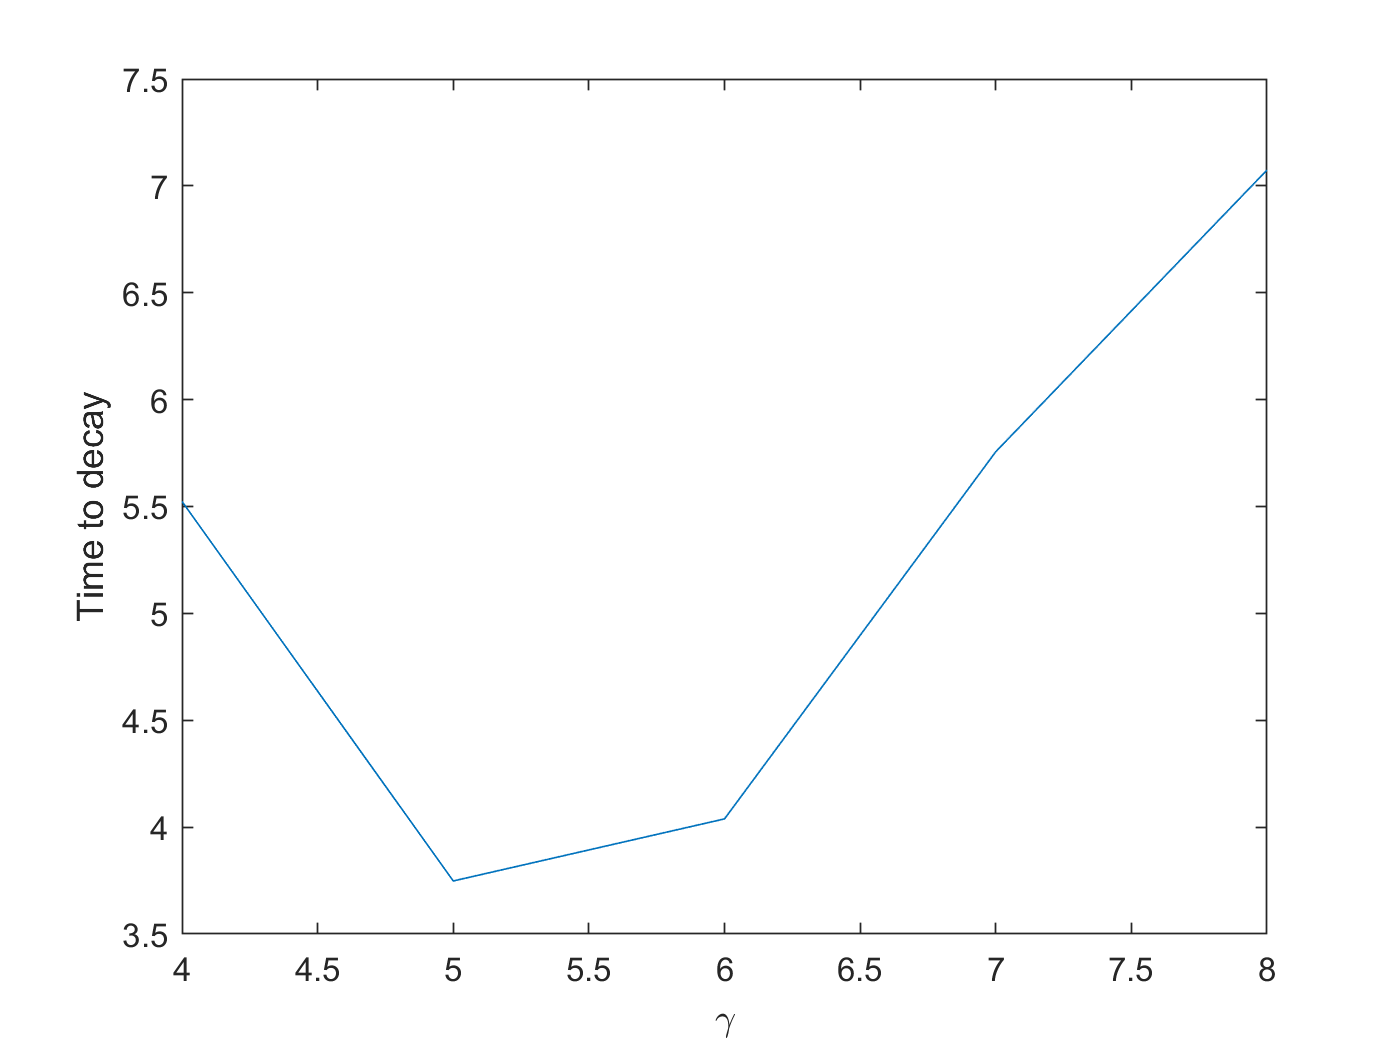

plot(gamma,T)
xlabel('\gamma')
ylabel('Time to decay')

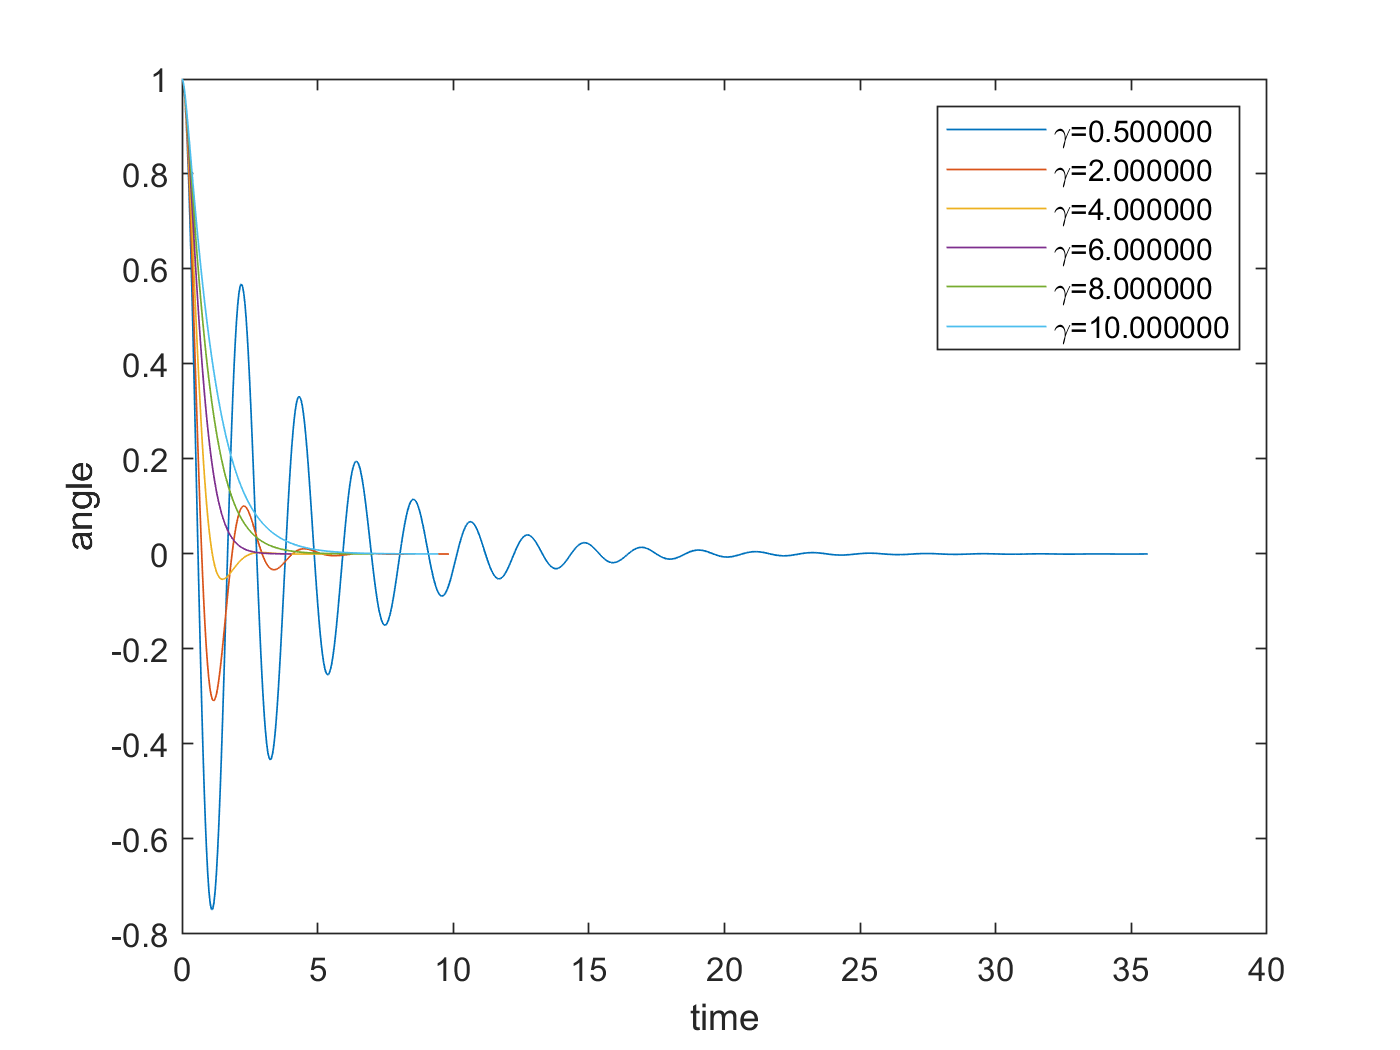



gamma = [0.5,2,4,6,8,10];
for k = 1:length(gamma)
    if k==1
        sol = struct('run1',0);
        fn = 'run1';
    else
        fn = sprintf('run%i',k);
    end
    [t,w] = pendulum2(4,0,omega0,theta0,thetadot0,gamma(k));
    sol = setfield(sol,fn,[t w]);
    T(k)=t(end);
end
solnames = fieldnames(sol);
for k = 1:length(solnames)
    W = getfield(sol,solnames{k});
    plot(W(:,1),W(:,2))
    hold on
    leglab(k) = sprintf("\\gamma=%f",gamma(k));
end
legend(leglab)
xlabel('time')
ylabel('angle')
hold off

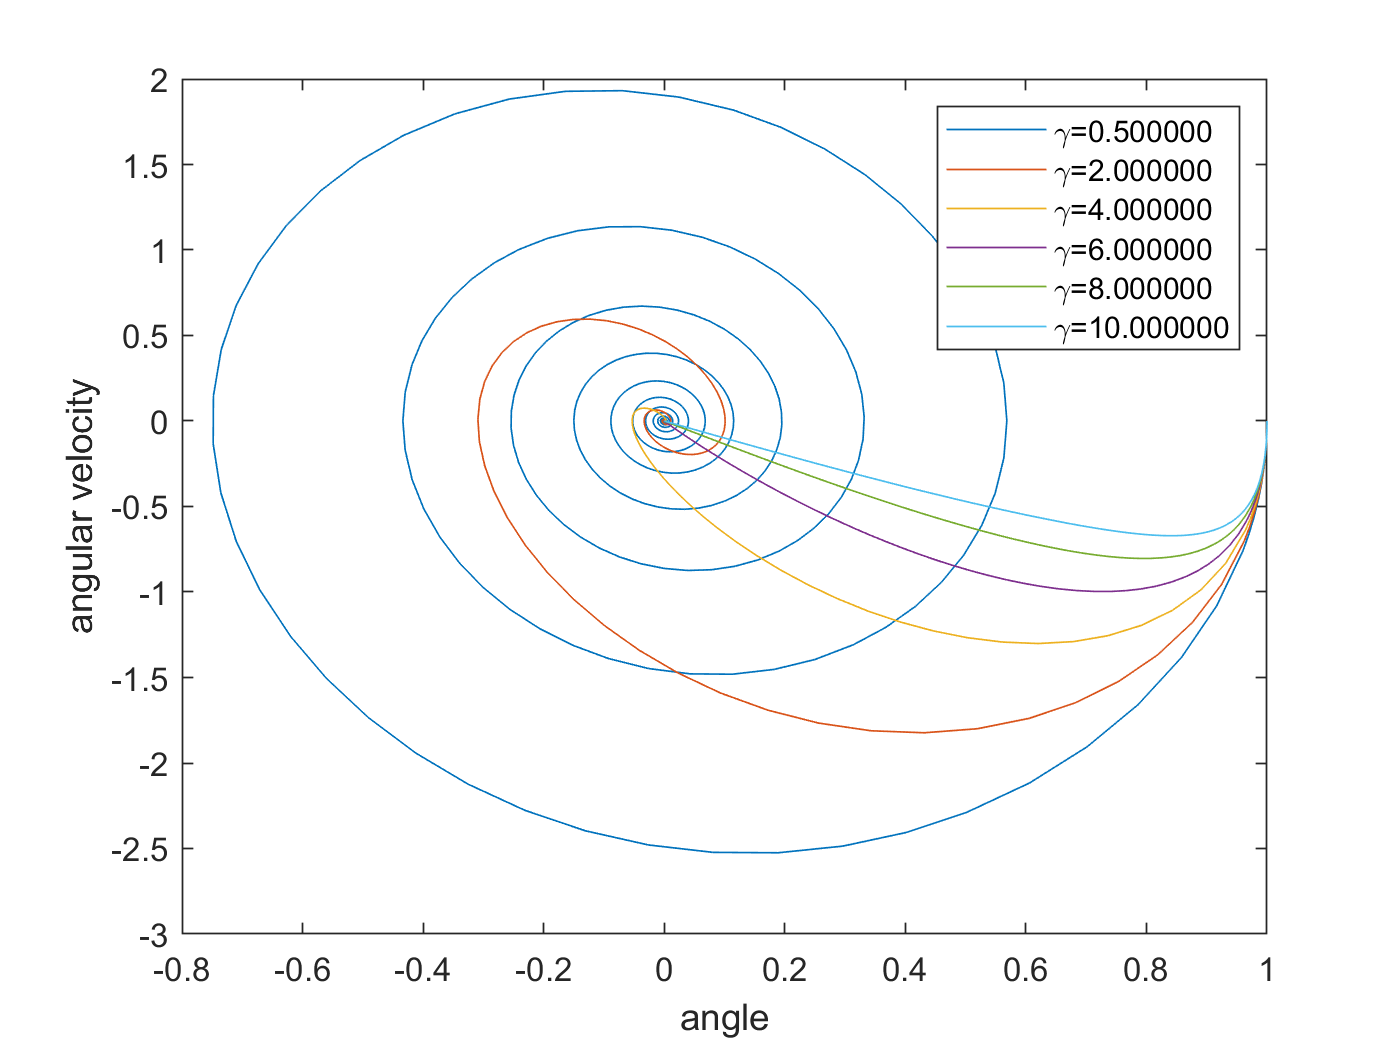

for k = 1:length(solnames)
    W = getfield(sol,solnames{k});
    plot(W(:,2),W(:,3))
    hold on
    leglab(k) = sprintf("\\gamma=%f",gamma(k));
end
hold off
xlabel('angle')
ylabel('angular velocity')
legend(leglab)

An interesting thing to note: the time to decay goes through a minimum as the oscillator goes from underdamped to overdamped motion.

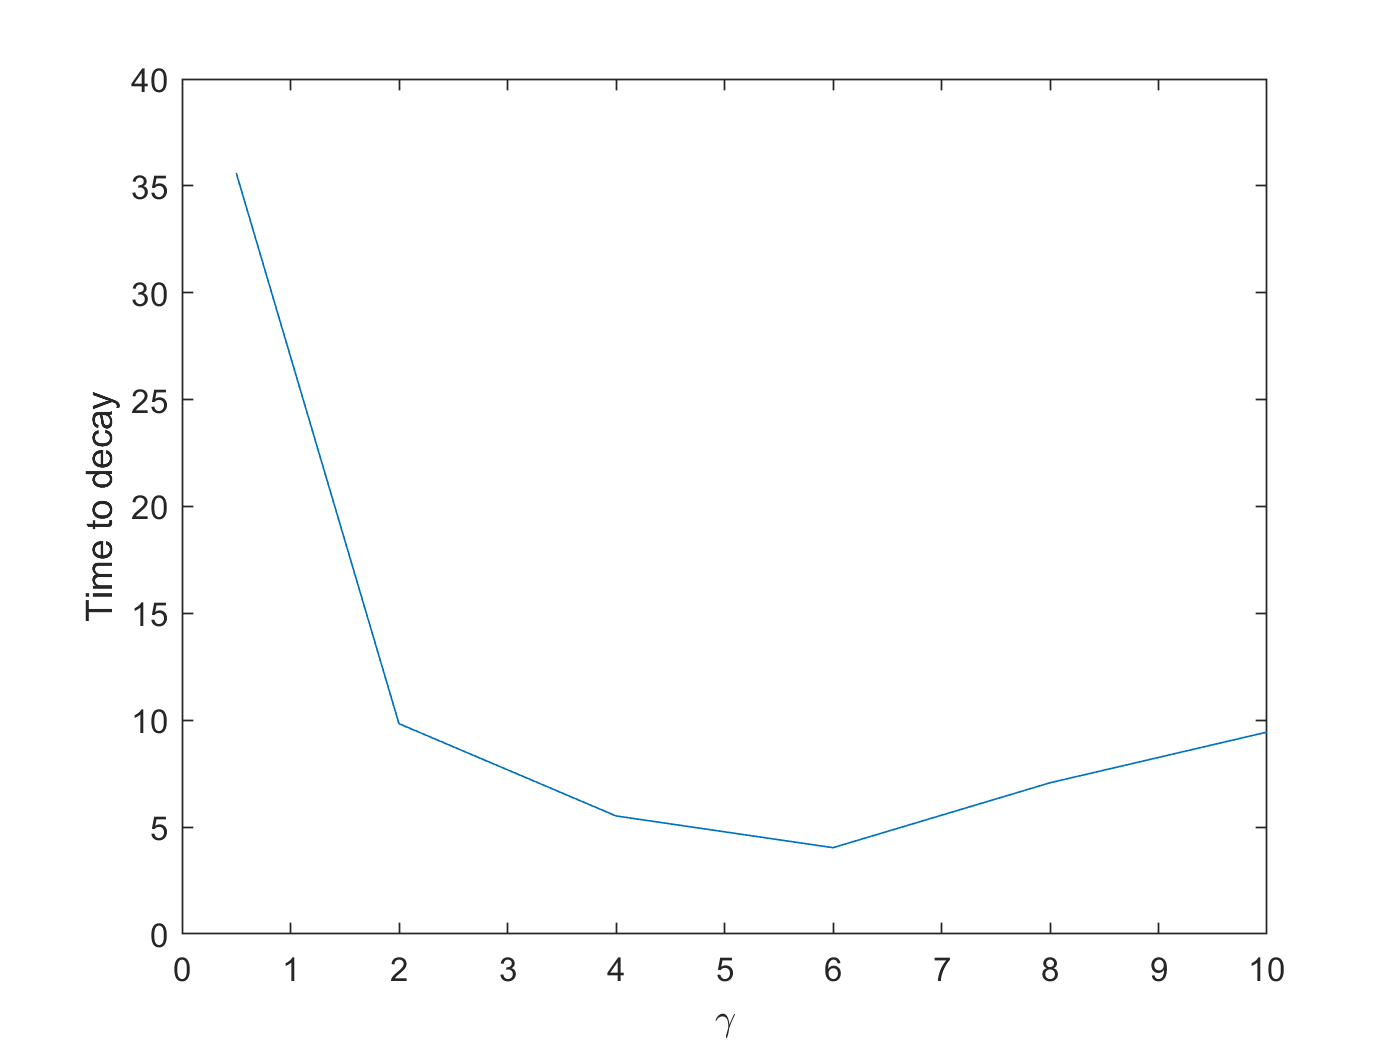

plot(gamma,T)
xlabel('\gamma')
ylabel('Time to decay')

## Problem 4: Driven Oscillations

For a driven damped harmonic oscillator,

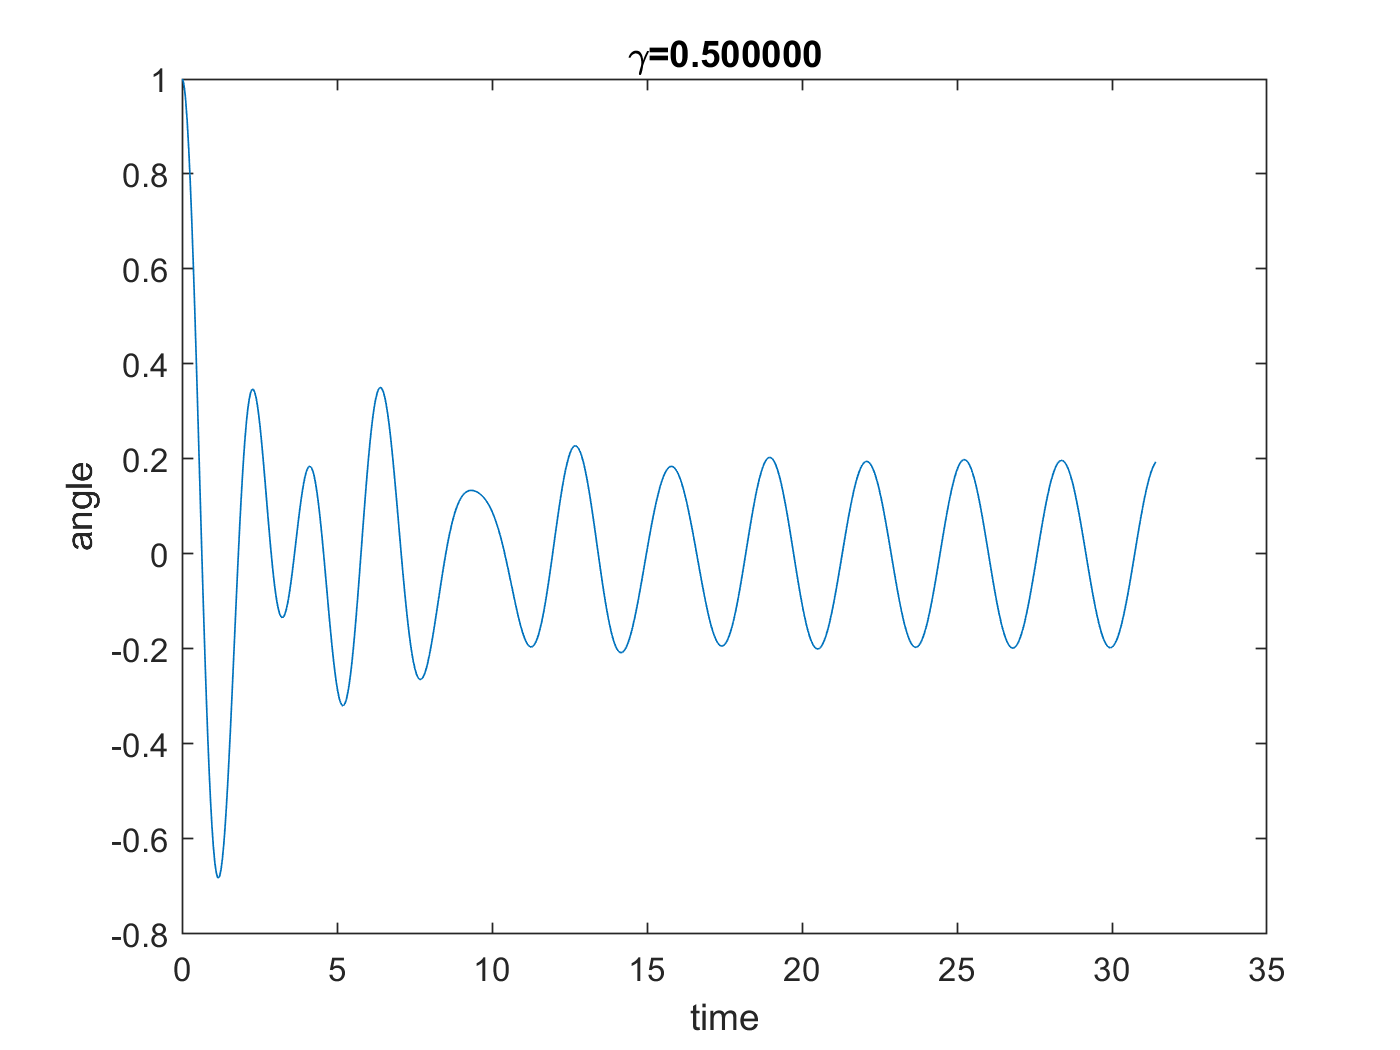

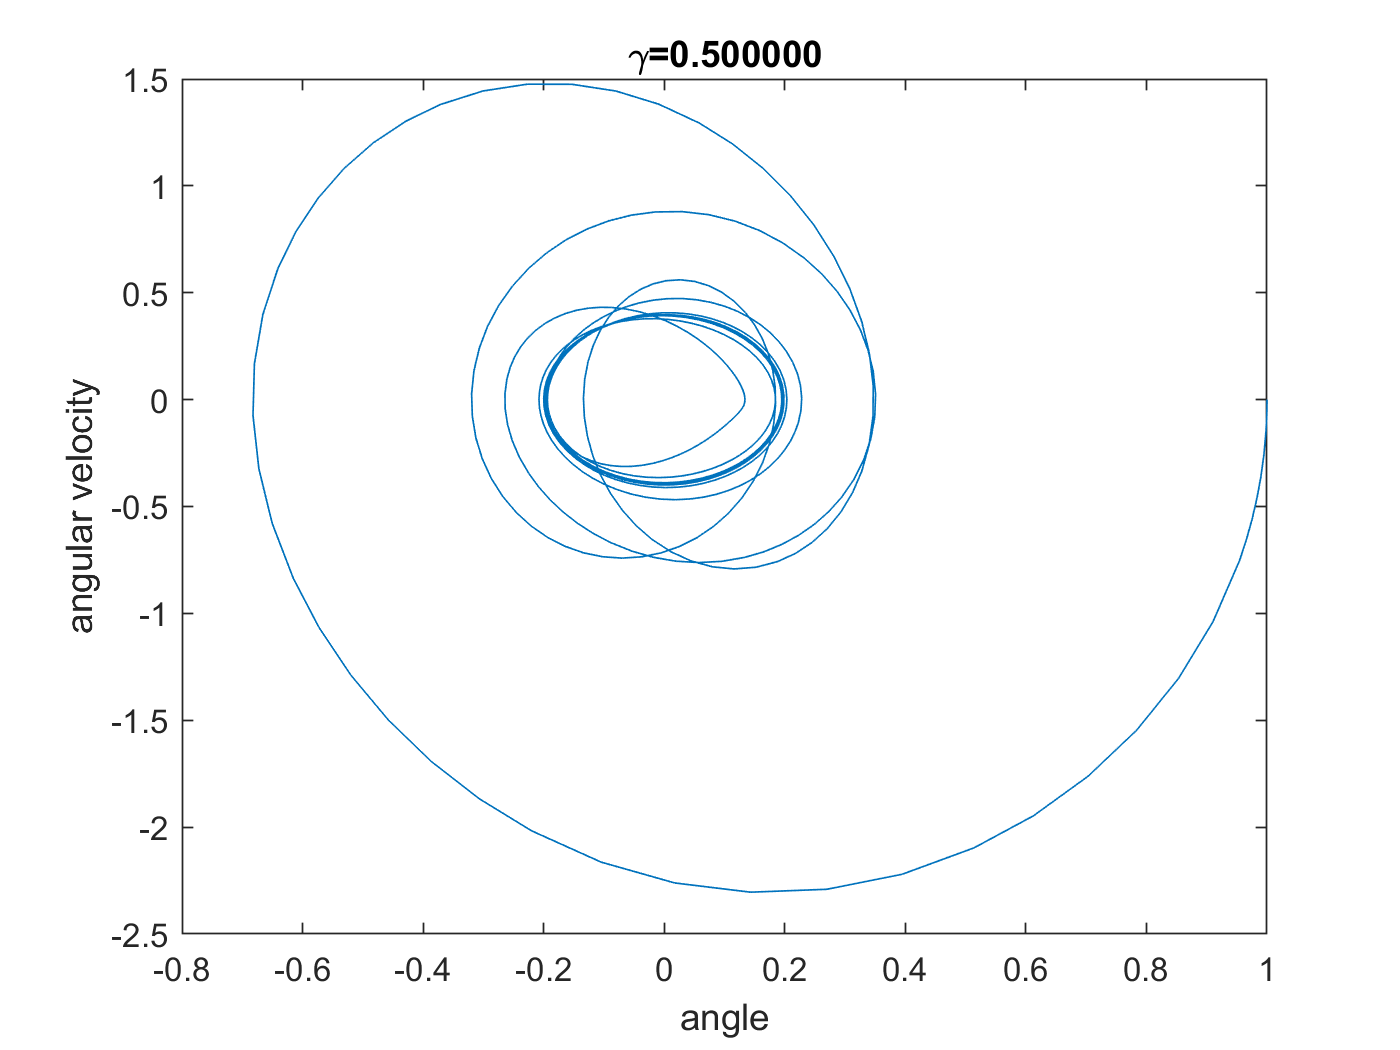

clear
g=9.81;
gamma = 0.5;
omega0=3;

omega=2;
theta0=1;
thetadot0=0;

[t,w] = pendulum2(5,1,omega0,theta0,thetadot0,gamma,omega);

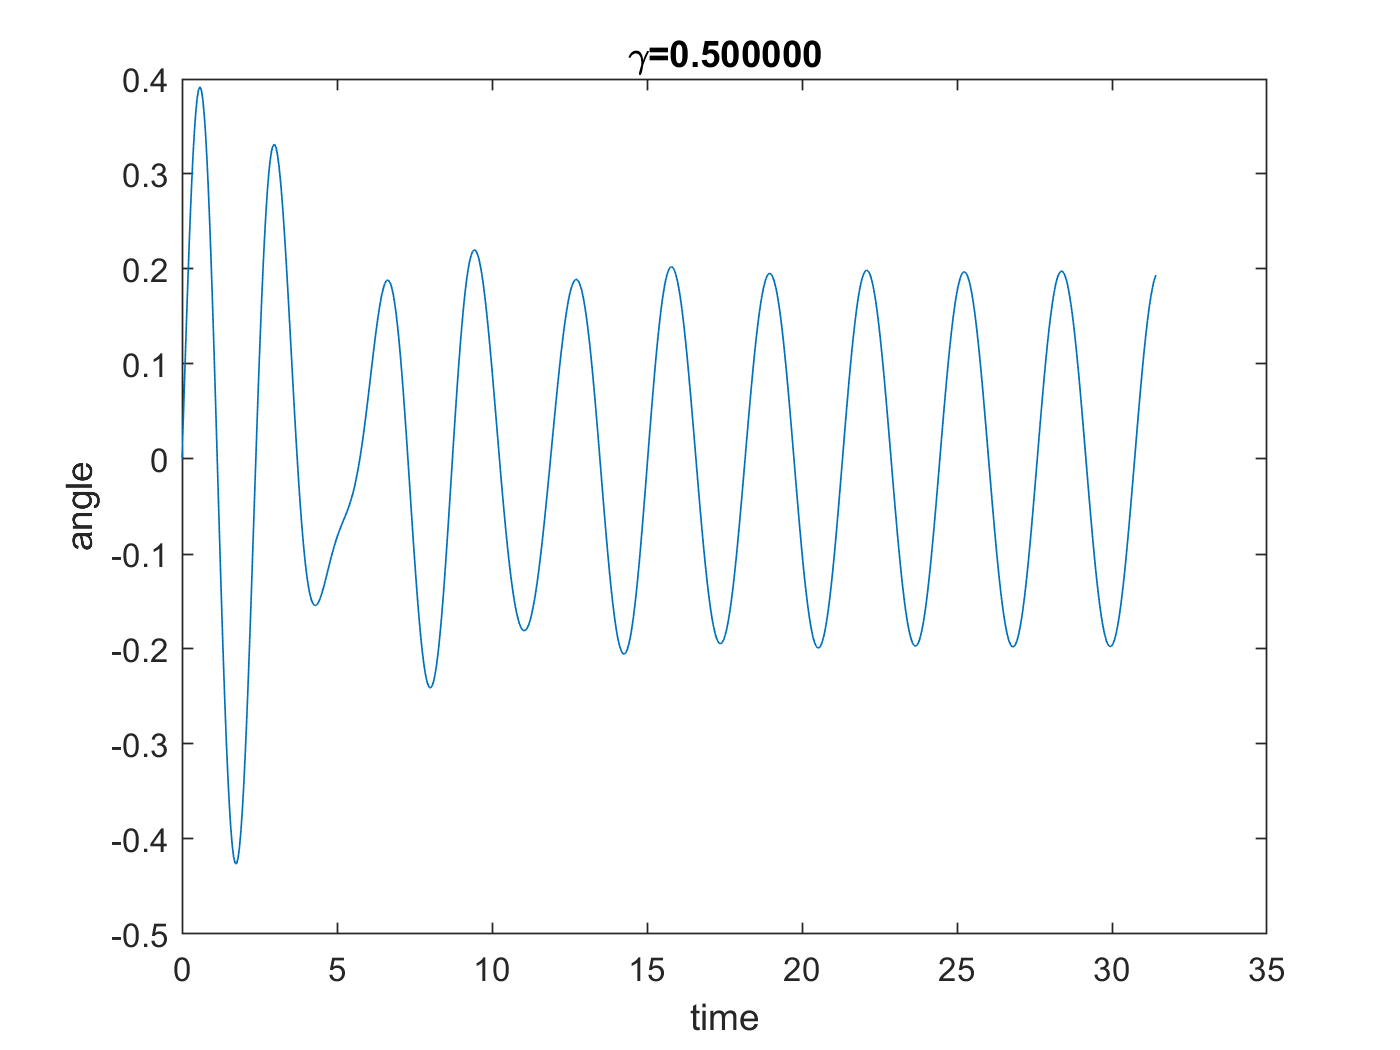

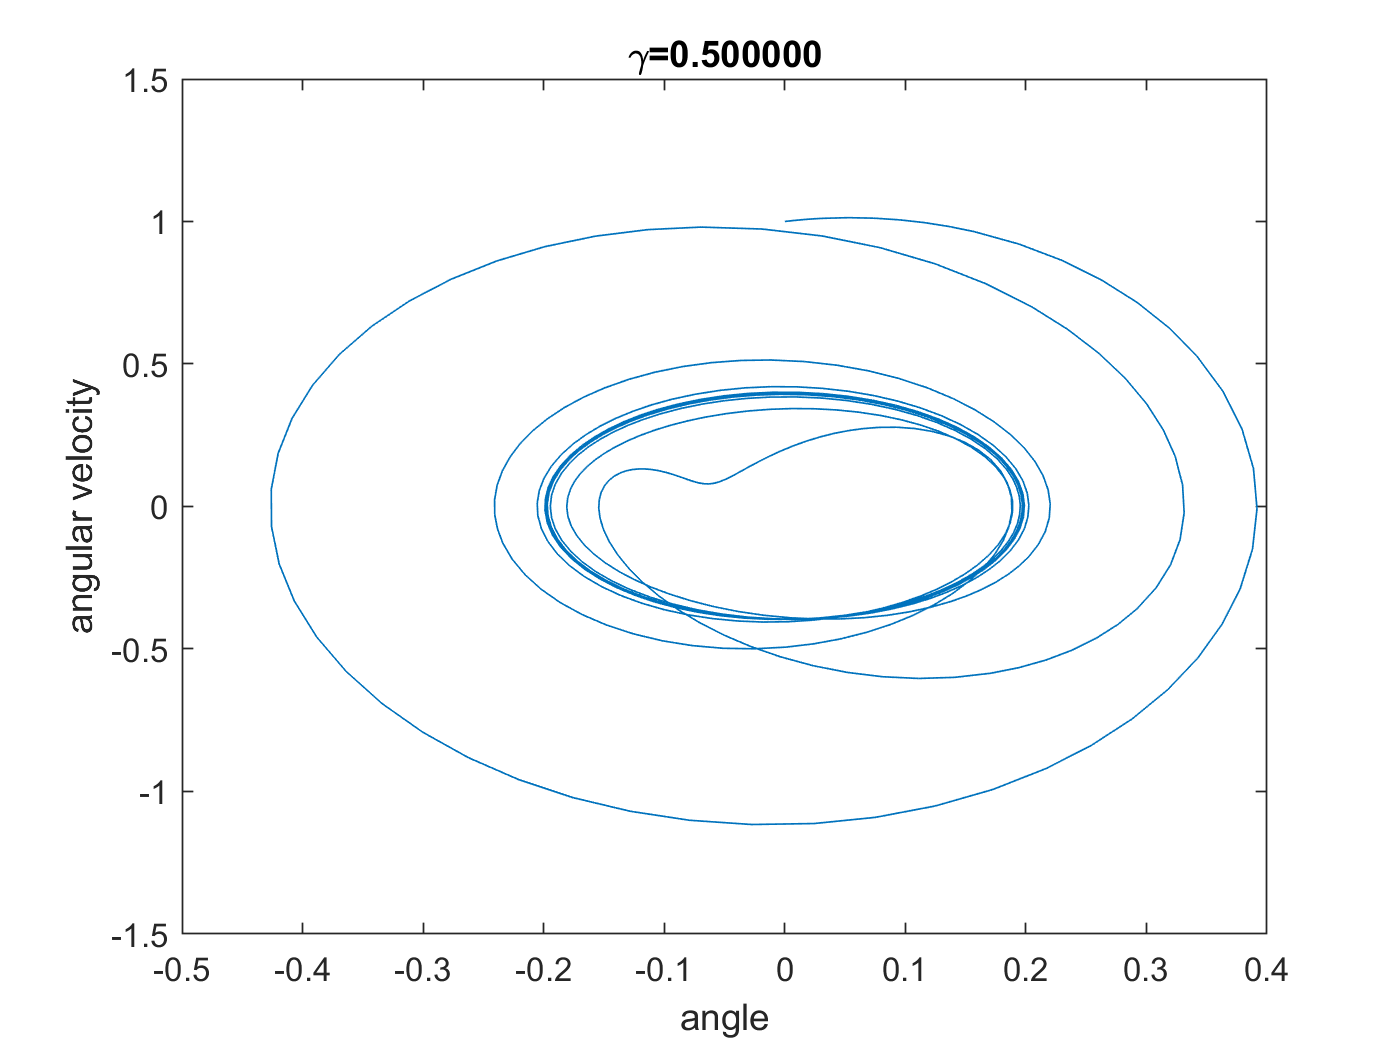

theta0=0;
thetadot0=1;
[t,w] = pendulum2(5,1,omega0,theta0,thetadot0,gamma,omega);

After several periods, you can see that the pendulum settles into the same oscillation frequency as the driving force. So, the transient part of the solution is the decaying oscillation of the damped oscillator and the steady state solution is dictated by the driving force. The transient solution depends on the initial conditions, but the steady state does not.

theta0=1;
thetadot0=1;
[t,w] = pendulum2(5,0,omega0,theta0,thetadot0,gamma,omega);
yss = 1/sqrt((omega0^2-omega^2)^2-gamma^2*omega^2)*cos(omega*t);
delta = mod(acos(w(:,1)/max(w(:,1)))-omega*t,2*pi)*2*pi

delta =    2.293803541183887
   2.156502710576413
   2.019284263572656
   1.882146631019917
   1.745088179008189
   1.608107191142514
   1.471201846450209
   0.787738922872081
   0.105774018065949
  38.902983522250615


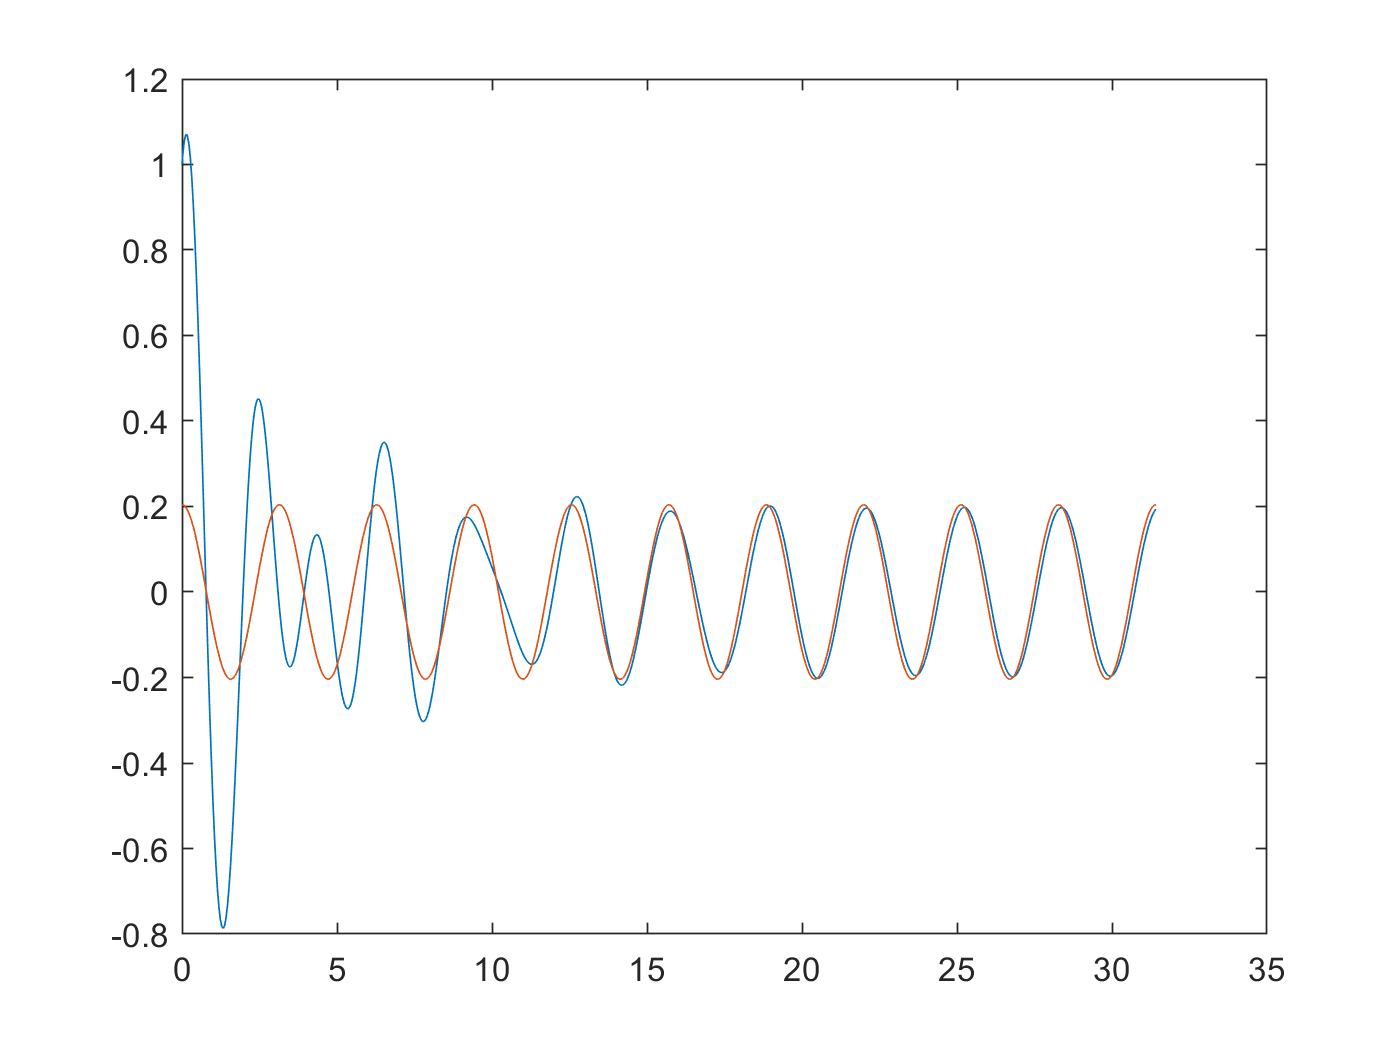

plot(t,w(:,1),t,yss)

## Problem 5: Resonances